# Load data and compute mean (from ass1)

if isfile('BI5_segments_HTS.mat')
    dataStruct = load('BI5_segments_HTS.mat');
else
    error('File BI5_segments_HTS.mat not found.');
end

segments = dataStruct.segments;
classes = dataStruct.classlabels;
t = dataStruct.t;
channels = dataStruct.ch_selection;

% find idx for each class. 1800 non-target, 400 target
idx_nontarget = find (classes == 1);
idx_target = find(classes == 2);

% get segments
segments_nontarget = segments(:, :, idx_nontarget);
segments_target = segments(:, :, idx_target);

% compute mean over the trials. We 3 channels and 77 time points, so
% result should be 3x77
mean_nontarget = mean(segments_nontarget, 3);
mean_target = mean(segments_target, 3);

# Compute SD

% for default normalization we set w=0 as per the docs
std_nontarget = std(segments_nontarget, 0, 3);
std_target = std(segments_target, 0, 3);

# Ploting with shaded error bar for SD

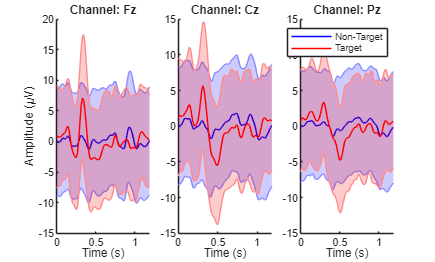

% Plot a figure for each channel with the two modalities (hold on).
figure('Name', 'P300 plot');

% Fz plot - just one legend
subplot(1, 3, 1);
shadedErrorBar(t, mean_nontarget(1, :), std_nontarget(1, :), 'lineprops', 'b'); 
hold on;
shadedErrorBar(t, mean_target(1, :), std_target(1, :), 'lineprops', 'r');
title(['Channel: ' channels{1}]);
xlabel('Time (s)');
ylabel('Amplitude (\muV)');

% Cz
subplot(1, 3, 2);
shadedErrorBar(t, mean_nontarget(2, :), std_nontarget(2, :), 'lineprops', 'b'); 
hold on;
shadedErrorBar(t, mean_target(2, :), std_target(2, :), 'lineprops', 'r');
title(['Channel: ' channels{2}]);
xlabel('Time (s)');

% Pz
subplot(1, 3, 3);
shadedErrorBar(t, mean_nontarget(3, :), std_nontarget(3, :), 'lineprops', 'b'); 
hold on;
shadedErrorBar(t, mean_target(3, :), std_target(3, :), 'lineprops', 'r');
title(['Channel: ' channels{3}]);
legend('Non-Target', 'Target');
xlabel('Time (s)');